# Exercise 2 

**a)**

Found out that spline interpolation gives the best graph.

close all
clear all
clc

motor = [0, 400, 800, 1200, 1600, 1763;
         8, 8.5, 9.0, 9.90, 7.15, 0];

fan   = [0, 400, 800, 1200;
         2, 3.8, 7.5, 14];

interpolation_type = 'spline';

graphSpeed = linspace(0,1800,1801);

MotorTorque = interp1(motor(1,:),motor(2,:),graphSpeed,interpolation_type);
FanTorque   = interp1(fan(1,:),fan(2,:),graphSpeed,interpolation_type);

The speed (in RPM) that gives the maximum allowed power, is the speed that gives


$$T_{motor} = 4.0 \: [in\cdot lb]$$


We find interception between the motor torque curve and the straight line $T\left(v\right)=4$ .

[MaxAllowedMotorSpeed, MaxAllowedMotorTorque] = interception(graphSpeed,MotorTorque,graphSpeed,4*ones(1,1801))

MaxAllowedMotorSpeed = 1.6870e+03

MaxAllowedMotorTorque = 4.0000

This gives max allowed Power [lb in rpm]

MaxAllowedPower = MaxAllowedMotorSpeed*MaxAllowedMotorTorque

MaxAllowedPower = 6.7479e+03

**b)**

Power is conserved in the system, so we need to find a set of torque and speed for the fan that matches the power output from the motor

PowerFan = FanTorque .* graphSpeed;
[MaxAllowedFanSpeed,~] = interception(graphSpeed,PowerFan,[0 1800],[MaxAllowedPower MaxAllowedPower])

MaxAllowedFanSpeed = 841.0620

[~,MaxAllowedFanTorque] = interception(graphSpeed, FanTorque,[MaxAllowedFanSpeed MaxAllowedFanSpeed+0.01],[0 14])

MaxAllowedFanTorque = 8.0231

Ratio for the motor and fan can be found by 


$$i =\frac{D_m}{D_f} = \frac{\omega_f}{\omega_m} = \frac{P \: T_m}{P\:T_f} = \frac{T_m}{T_f}$$


beltRatio = MaxAllowedMotorTorque/MaxAllowedFanTorque 

beltRatio = 0.4986

**c)** 

Newtons second law of


$$\sum{T} =  \frac{d}{dt}\Big(I\cdot \omega \Big)$$



$$T_m-T_f = \frac{d}{dt}\Big(I\cdot \omega \Big)$$


Timediscretizisation using an explicit forward euler scheme.


$$\omega^{n+1} = \omega^n + \frac{T_m-T_f}{I}\cdot \Delta t$$


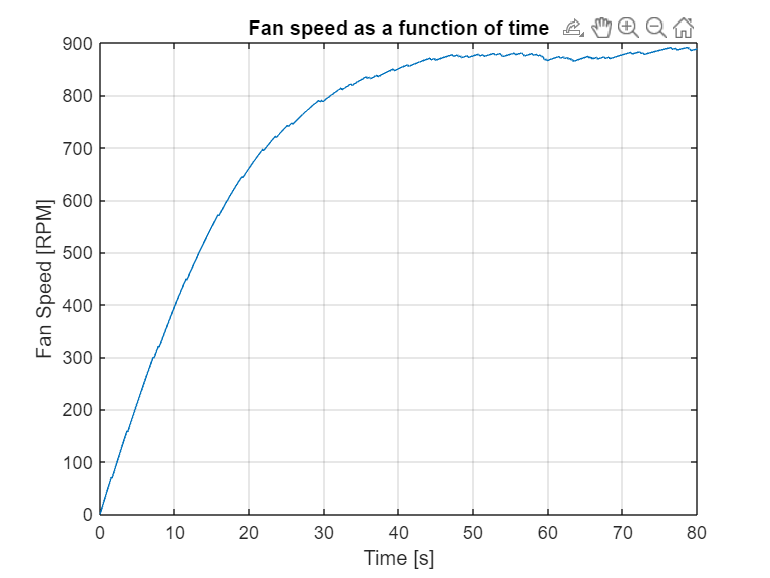

I = 1.2;
tmax = 80;
dt = 0.1;
tol = 0.001;
omegaFan = 0;
PowerMotor = graphSpeed.*MotorTorque;

i = 0;
tVector = zeros(1,ceil(tmax/dt));
omegaVector = zeros(1,ceil(tmax/dt));

for t = 0:dt:tmax
    i = i + 1;
    [~, Tf] = interception(graphSpeed, FanTorque,[omegaFan omegaFan+0.001],[0 20]);
    ConstantPower = omegaFan*Tf;
    [omegaMotor, ~] = interception(graphSpeed, PowerMotor,[0 1800], [ConstantPower ConstantPower+0.001]);
    [~, Tm] = interception(graphSpeed, MotorTorque,[omegaMotor omegaMotor+0.001], [0 20]);
    omegaFan_new = omegaFan+((Tm-Tf)/I*dt)*60/(2*pi); % converting the additve term to rpm from 1/s
    %disp(" time[s] = "+num2str(t)+" omega_fan = "+num2str(omegaFan_new))
    tVector(i) = t;
    omegaVector(i) = omegaFan;
    omegaFan = omegaFan_new;
    switch i
        case {1,2,3,4,5,6}  
        otherwise
            avg = 1/5*(omegaVector(i-5)+omegaVector(i-4)+omegaVector(i-3)+omegaVector(i-2)+omegaVector(i-1));
            if abs(avg-omegaFan)<tol
                break
            end
    end
end

tVectorSliced = tVector(1:i);
omegaVectorSliced = omegaVector(1:i);

plot(tVectorSliced,omegaVectorSliced)
grid on
title('Fan speed as a function of time')
xlabel('Time [s]')
ylabel('Fan Speed [RPM]')

Ble litt vanskelig med stopping kriteriet når grafen ble veldig veldig ruglete

### **Functions**

*Interception(x1,y1,x2,y2)*

Find the interception point of two graphs on vector form.

function [xcross,ycross] = interception(x1,y1,x2,y2)
% Find intersections between two arrays y1 and y2

xstart = max(x1(1),x2(1));
xstop  = min(x1(end),x2(end));
x      = linspace(xstart,xstop,(xstop-xstart)*1000 + 1);
y1_int = interp1(x1,y1,x,'linear');
y2_int = interp1(x2,y2,x,'linear');

diff_vec = abs(y2_int-y1_int);
minDiff  = min(diff_vec);
minIndex = find(diff_vec == minDiff);
xcross = x(minIndex);
ycross = y1_int(minIndex);
end